clear; clc; close all;

Set the random number generator to Mersenne Twister

rng(100,"twister")

Read the numeric 

x = readcell('companyData.xlsx')

x = 393x37 cell array
    {'Company'    }    {'AAPL'   }    {'NOW'   }    {'MSFT'  }    {'GOOGL' }    {'HD'    }    {'W'       }    {'COST'  }    {'HSY'   }    {'KDP'    }    {'CLX'    }    {'XOM'   }    {'CVX'   }    {'HAL'   }    {'JPM'   }    {'MS'    }    {'V'     }    {'UNH'    }    {'PFE'    }    {'DXCM'   }    {'RTX'    }    {'FDX'   }    {'LHX'    }    {'ECL'   }    {'SHW'   }    {'SCCO'   }    {'LIN'   }    {'PLD'   }    {'AMT'    }    {'EXR'   }    {'KIM'    }    {'SLG'    }    {'D'      }    {'DUK'    }    {'AEP'   }    {'ES'     }    {'PCG'    }
    {'ROA Q4 2024'}    {[10.5584]}    {[1.8839]}    {[4.5155]}    {[7.8060]}    {[3.1180]}    {[ -3.7005]}    {[2.4501]}    {[6.1528]}    {[-0.2695]}    {[ 3.4606]}    {[1.6782]}    {[1.2606]}    {[2.4036]}    {[0.3499]}    {[0.3057]}    {[5.5709]}    {[ 1.8583]}    {[ 0.1921]}    {[ 2.3394]}    {[ 0.9100]}    {[4.1815]}    {[13.1497]}    {[2.1123]}    {[2.0315]}    {[ 4.3867]}    {[1.8777]}    {[1.3415]}    {[ 2.0132]}    {[0.9099]

Achieve the company's name by getting all the name of the first column

companyNames = x(1, 2:end)

companyNames = 1x36 cell array
    {'AAPL'}    {'NOW'}    {'MSFT'}    {'GOOGL'}    {'HD'}    {'W'}    {'COST'}    {'HSY'}    {'KDP'}    {'CLX'}    {'XOM'}    {'CVX'}    {'HAL'}    {'JPM'}    {'MS'}    {'V'}    {'UNH'}    {'PFE'}    {'DXCM'}    {'RTX'}    {'FDX'}    {'LHX'}    {'ECL'}    {'SHW'}    {'SCCO'}    {'LIN'}    {'PLD'}    {'AMT'}    {'EXR'}    {'KIM'}    {'SLG'}    {'D'}    {'DUK'}    {'AEP'}    {'ES'}    {'PCG'}


featureNames = x(2:end,1)

featureNames = 392x1 cell array
    {'ROA Q4 2024'}
    {'ROA Q3 2024'}
    {'ROA Q2 2024'}
    {'ROA Q1 2024'}
    {'ROA Q4 2023'}
    {'ROA Q3 2023'}
    {'ROA Q2 2023'}
    {'ROA Q1 2023'}
    {'ROA Q4 2022'}
    {'ROA Q3 2022'}
    {'ROA Q2 2023'}
    {'ROA Q1 2022'}
    {'ROA Q4 2021'}
    {'ROA Q3 2021'}
    {'ROA Q2 2021'}
    {'ROA Q1 2021'}
    {'ROA Q4 2020'}
    {'ROA Q3 2020'}
    {'ROA Q2 2020'}
    {'ROA Q1 2020'}
    {'ROA Q4 2019'}
    {'ROA Q3 2019'}
    {'ROA Q2 2019'}
    {'ROA Q1 2019'}
    {'ROA Q4 2018'}
    {'ROA Q3 2018'}
    {'ROA Q2 2018'}
    {'ROA Q1 2018'}
    {'ROE Q4 2024'}
    {'ROE Q3 2024'}


Extract data

x = x(2:end, 2:end)

x = 392x36 cell array
    {[10.5584]}    {[1.8839]}    {[4.5155]}    {[7.8060]}    {[3.1180]}    {[ -3.7005]}    {[2.4501]}    {[6.1528]}    {[-0.2695]}    {[ 3.4606]}    {[1.6782]}    {[1.2606]}    {[2.4036]}    {[0.3499]}    {[0.3057]}    {[5.5709]}    {[ 1.8583]}    {[ 0.1921]}    {[ 2.3394]}    {[ 0.9100]}    {[4.1815]}    {[13.1497]}    {[2.1123]}    {[2.0315]}    {[ 4.3867]}    {[1.8777]}    {[1.3415]}    {[ 2.0132]}    {[0.9099]}    {[ 0.8175]}    {[ 0.1828]}    {[-0.0547]}    {[ 0.6391]}    {[0.6443]}    {[ 0.1217]}    {[ 0.5043]}
    {[ 4.0375]}    {[2.3435]}    {[4.7163]}    {[6.1127]}    {[3.7506]}    {[ -2.1675]}    {[3.3710]}    {[3.5361]}    {[ 1.1685]}    {[ 1.8010]}    {[1.8640]}    {[1.7309]}    {[2.2542]}    {[0.3064]}    {[0.2534]}    {[5.6269]}    {[ 2.0230]}    {[ 2.0344]}    {[ 2.1184]}    {[ 0.8931]}    {[4.3882]}    {[12.6334]}    {[3.3323]}    {[3.3636]}    {[ 4.7227]}    {[2.0732]}    {[1.0487]}    {[-1.2613]}    {[0.6885]}    {[ 0.6756]}    {[-0.0907]}    {[ 

x = cell2mat(x)

x = 1.0e+04 *

    0.0011    0.0002    0.0005    0.0008    0.0003   -0.0004    0.0002    0.0006   -0.0000    0.0003    0.0002    0.0001    0.0002    0.0000    0.0000    0.0006    0.0002    0.0000    0.0002    0.0001    0.0004    0.0013    0.0002    0.0002    0.0004    0.0002    0.0001    0.0002    0.0001    0.0001    0.0000   -0.0000    0.0001    0.0001    0.0000    0.0001
    0.0004    0.0002    0.0005    0.0006    0.0004   -0.0002    0.0003    0.0004    0.0001    0.0002    0.0002    0.0002    0.0002    0.0000    0.0000    0.0006    0.0002    0.0002    0.0002    0.0001    0.0004    0.0013    0.0003    0.0003    0.0005    0.0002    0.0001   -0.0001    0.0001    0.0001   -0.0000    0.0001    0.0001    0.0001   -0.0000    0.0000
    0.0006    0.0001    0.0004    0.0006    0.0005   -0.0001    0.0002    0.0001    0.0001    0.0004    0.0002    0.0002    0.0003    0.0000    0.0000    0.0005    0.0001    0.0000    0.0002    0.0000    0.0008    0.0013    0.0002    0.0004    0.0005    0.0002   

Create and train Self-Organizing Map (SOM)

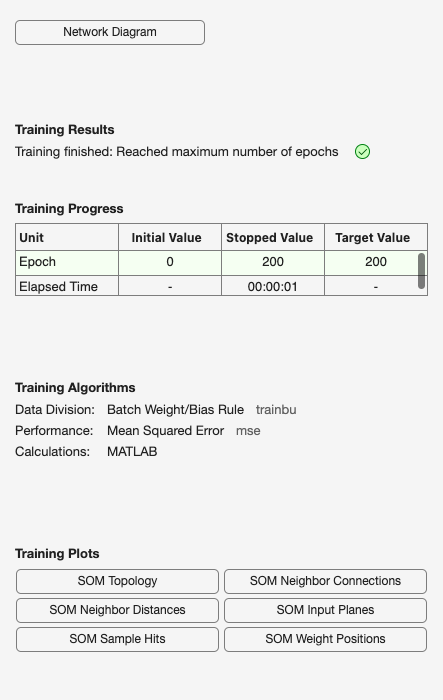

net = selforgmap([7 7]); 
[net,tr] = train(net,x);

Visualize SOM

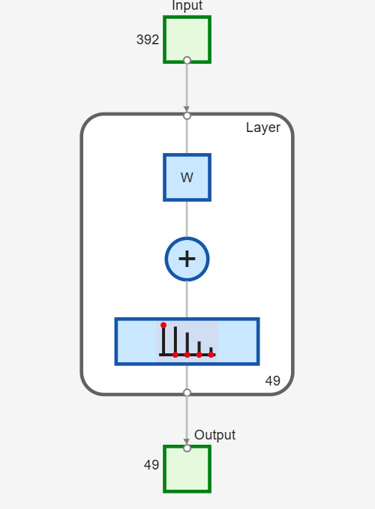

view(net);

 The network output will be a 393x37 matrix, where each ith column represents the jth cluster for each ith input vector with a 1 in its jth element

y = net(x);

The function `vec2ind` returns the index of the neuron with an output of 1, for each vector. The indices will range between 1 and 49

classes = vec2ind(y);

`plotsomtop` plots the SOM topology of 49 neurons positioned in an 7x7 hexagonal grid.

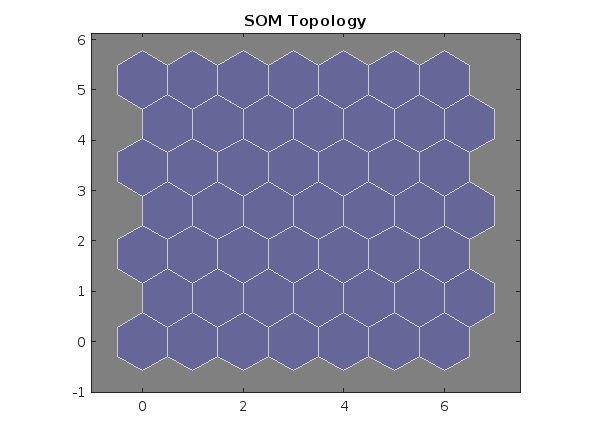

plotsomtop(net);

% Display mappings
for i = 1:numel(companyNames)
    fprintf('Company: %-20s → Neuron Index: %d\n', companyNames{i}, classes(i));
end

Company: AAPL                 → Neuron Index: 19
Company: NOW                  → Neuron Index: 7
Company: MSFT                 → Neuron Index: 25
Company: GOOGL                → Neuron Index: 19
Company: HD                   → Neuron Index: 42
Company: W                    → Neuron Index: 41
Company: COST                 → Neuron Index: 19
Company: HSY                  → Neuron Index: 24
Company: KDP                  → Neuron Index: 19
Company: CLX                  → Neuron Index: 39
Company: XOM                  → Neuron Index: 9
Company: CVX                  → Neuron Index: 12
Company: HAL                  → Neuron Index: 23
Company: JPM                  → Neuron Index: 18
Company: MS                   → Neuron Index: 18
Company: V                    → Neuron Index: 19
Company: UNH                  → Neuron Index: 19
Company: PFE                  → Neuron Index: 29
Company: DXCM                 → Neuron Index: 1
Company: RTX                  → Neuron Index: 43
Company: FDX           

These are 10 companies at the same spot (index 19) . First, we find indices where the neuron index is 19.

fprintf('Companies at Neuron Index 19:\n');

Companies at Neuron Index 19:


idx19=find(classes ==19);
for i = 1:prod(size(idx19))
    fprintf('%s,', companyNames{idx19(i)});
end

AAPL,GOOGL,COST,KDP,V,UNH,LHX,SHW,PLD,EXR,

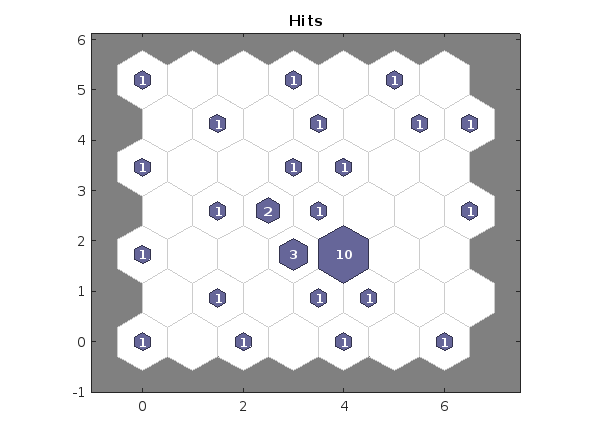

plotsomhits(net, x);

`There are 10 companies:AAPL,GOOGL,COST,KDP,V,UNH,LHX,SHW,PLD,EXR`

`plotsomnc` shows the neuron neighbor connections. Neighbors typically classify similar company

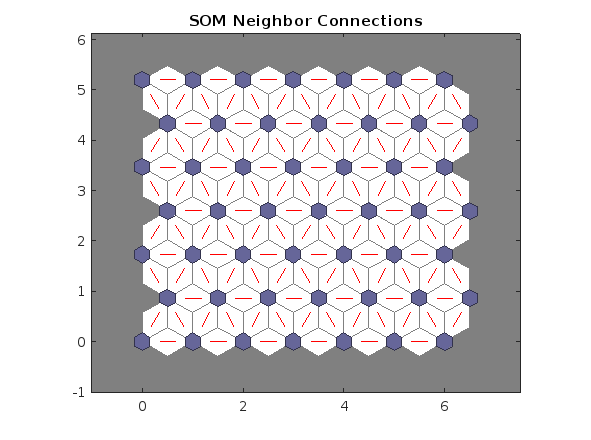

plotsomnc(net);

plotsomnd(net);